%%loading the data
clear all 
close all 
hit=0;
miss=0;
shaking=load('shaking4.mat');%%load shaking data
steady=load('steady.mat');%%load steady data
jumping=load('jumping.mat');%%load jumping data
data={};
for i=1:length(shaking.Acceleration.X)
data(i,:)={shaking.Acceleration.X(i), shaking.Acceleration.Y(i), shaking.Acceleration.Z(i), 'shaking'};
end
for i=length(shaking.Acceleration.X)+1:(length(shaking.Acceleration.X)+length(steady.Acceleration.X))
    for j=1:length(steady.Acceleration.X)
        data(i,:)={steady.Acceleration.X(j), steady.Acceleration.Y(j), steady.Acceleration.Z(j), 'steady'};
    end
end
for i=length(shaking.Acceleration.X)+length(steady.Acceleration.X)+1:(length(shaking.Acceleration.X)+length(steady.Acceleration.X))+length(jumping.Acceleration.X)
    for j=1:length(jumping.Acceleration.X)
        data(i,:)={jumping.Acceleration.X(j), jumping.Acceleration.Y(j), jumping.Acceleration.Z(j), 'jumping'};
    end
end
X=cell2mat(data(:,1));
Y=cell2mat(data(:,2));
Z=cell2mat(data(:,3));

x=[X,Y]

x =     1.6029    6.2773
    2.3489    6.6245
    2.7921    6.4244
    1.0065    4.8245
   -0.2225    4.1082
   -1.7414    3.6772
    0.1331    1.8742
   -0.7944    3.7950
    3.1884    9.1107
    5.3363   10.3038


xlab = "Points sorted with nearest distances of 1"

ylab = "Nearest distances of 1"

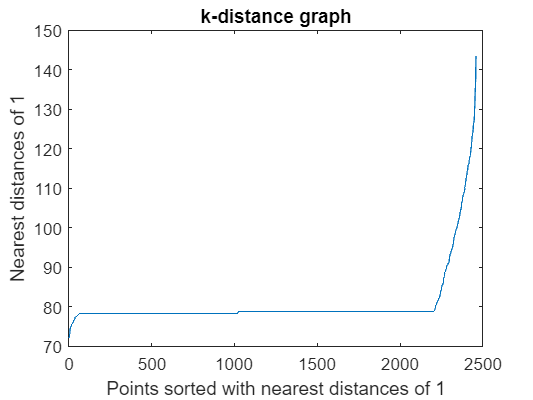

xlab = "Points sorted with nearest distances of 2"

ylab = "Nearest distances of 2"

xlab = "Points sorted with nearest distances of 3"

ylab = "Nearest distances of 3"

xlab = "Points sorted with nearest distances of 4"

ylab = "Nearest distances of 4"

xlab = "Points sorted with nearest distances of 5"

ylab = "Nearest distances of 5"

xlab = "Points sorted with nearest distances of 6"

ylab = "Nearest distances of 6"

xlab = "Points sorted with nearest distances of 7"

ylab = "Nearest distances of 7"

xlab = "Points sorted with nearest distances of 8"

ylab = "Nearest distances of 8"

xlab = "Points sorted with nearest distances of 9"

ylab = "Nearest distances of 9"

xlab = "Points sorted with nearest distances of 10"

ylab = "Nearest distances of 10"

xlab = "Points sorted with nearest distances of 11"

ylab = "Nearest distances of 11"

xlab = "Points sorted with nearest distances of 12"

ylab = "Nearest distances of 12"

xlab = "Points sorted with nearest distances of 13"

ylab = "Nearest distances of 13"

xlab = "Points sorted with nearest distances of 14"

ylab = "Nearest distances of 14"

xlab = "Points sorted with nearest distances of 15"

ylab = "Nearest distances of 15"

xlab = "Points sorted with nearest distances of 16"

ylab = "Nearest distances of 16"

xlab = "Points sorted with nearest distances of 17"

ylab = "Nearest distances of 17"

xlab = "Points sorted with nearest distances of 18"

ylab = "Nearest distances of 18"

xlab = "Points sorted with nearest distances of 19"

ylab = "Nearest distances of 19"

xlab = "Points sorted with nearest distances of 20"

ylab = "Nearest distances of 20"

xlab = "Points sorted with nearest distances of 21"

ylab = "Nearest distances of 21"

xlab = "Points sorted with nearest distances of 22"

ylab = "Nearest distances of 22"

xlab = "Points sorted with nearest distances of 23"

ylab = "Nearest distances of 23"

xlab = "Points sorted with nearest distances of 24"

ylab = "Nearest distances of 24"

xlab = "Points sorted with nearest distances of 25"

ylab = "Nearest distances of 25"

xlab = "Points sorted with nearest distances of 26"

ylab = "Nearest distances of 26"

xlab = "Points sorted with nearest distances of 27"

ylab = "Nearest distances of 27"

xlab = "Points sorted with nearest distances of 28"

ylab = "Nearest distances of 28"

xlab = "Points sorted with nearest distances of 29"

ylab = "Nearest distances of 29"

xlab = "Points sorted with nearest distances of 30"

ylab = "Nearest distances of 30"

%for trying diffrent types of distance with diffrent near neighbour number
for minpts=1:1:30
kD = pdist2(x,x,'euc','Largest',minpts); % The minpts smallest pairwise distances 
figure 
plot(sort(kD(end,:))); 
title('k-distance graph') 
xlab='Points sorted with nearest distances of '+ string(minpts) 
xlabel(xlab) 
ylab='Nearest distances of '+ string(minpts) 
ylabel(ylab) 
rng('default') % For reproducibility 
eps=0.3; 
%% enter the different types of distance in the place of jaccard
idx = dbscan(x,eps,minpts,'Distance','jaccard'); % The default distance metric is Euclidean distance
figure 
gscatter(x(:,1),x(:,2),idx); 
end

% Since the I got better results for mpint 2 i kept this code
minpts = 2; 
kD = pdist2(x,x,'euc','Smallest',minpts); % The minpts smallest pairwise distances 
figure 
plot(sort(kD(end,:))); 
title('k-distance graph') 
xlab='Points sorted with nearest distances of '+ string(minpts) 

xlab = "Points sorted with nearest distances of 2"

xlabel(xlab) 
ylab='Nearest distances of '+ string(minpts) 

ylab = "Nearest distances of 2"

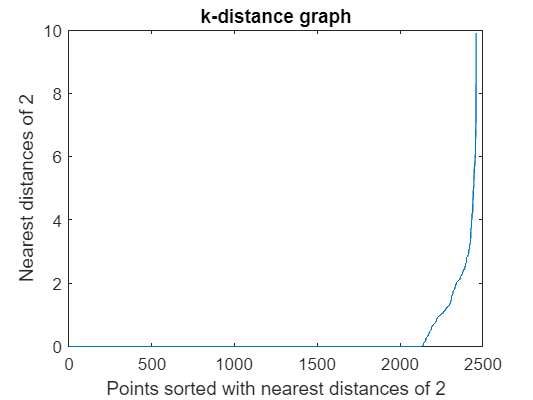

ylabel(ylab) 

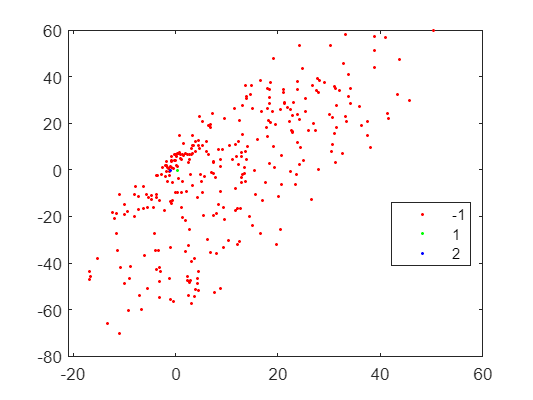

rng('default') % For reproducibility 
eps=0.3; 
idx = dbscan(x,eps,minpts,'Distance','jaccard'); % The default distance metric is Euclidean distance 
figure 
gscatter(x(:,1),x(:,2),idx); 

%%repeated the Part one of this homework to check if the results were same
data=[x Z idx]%%idx is the output for minpts=2

data =     1.6029    6.2773    6.8934   -1.0000
    2.3489    6.6245    6.4235   -1.0000
    2.7921    6.4244    7.0361   -1.0000
    1.0065    4.8245    7.8281   -1.0000
   -0.2225    4.1082   10.9367   -1.0000
   -1.7414    3.6772    6.0823   -1.0000
    0.1331    1.8742   11.7132   -1.0000
   -0.7944    3.7950   12.5076   -1.0000
    3.1884    9.1107   10.3995   -1.0000
    5.3363   10.3038   10.2820   -1.0000


rng(4)
data =  data(randperm(end),:);
Xdata=data(:,1:3)

Xdata =     0.3831   -0.4716    9.7296
   -1.0277   -0.0781    9.7834
    0.3831   -0.4716    9.7296
   -1.0277   -0.0781    9.7834
   -1.0277   -0.0781    9.7834
   -1.0277   -0.0781    9.7834
   -1.0277   -0.0781    9.7834
   -1.0277   -0.0781    9.7834
    0.3831   -0.4716    9.7296
   -1.0277   -0.0781    9.7834


Ydata=data(:,4)

Ydata =      1
     2
     1
     2
     2
     2
     2
     2
     1
     2


Xtraindata=Xdata((1:round(0.8*length(Xdata))),:);
Xtestdata=Xdata((round(0.8*length(Xdata)):end),:);
Ytraindata=Ydata((1:round(0.8*length(Ydata))),:);
Ytestdata=Ydata((round(0.8*length(Ydata)):end),:);


j = 1

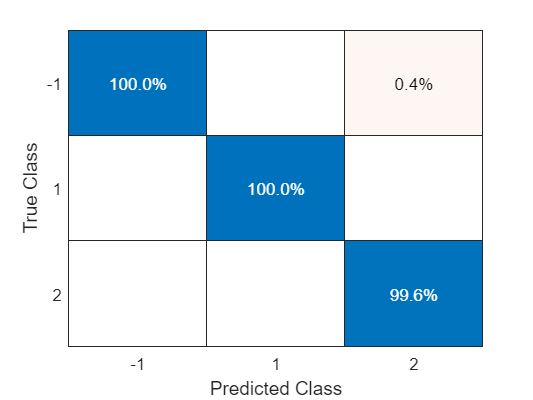

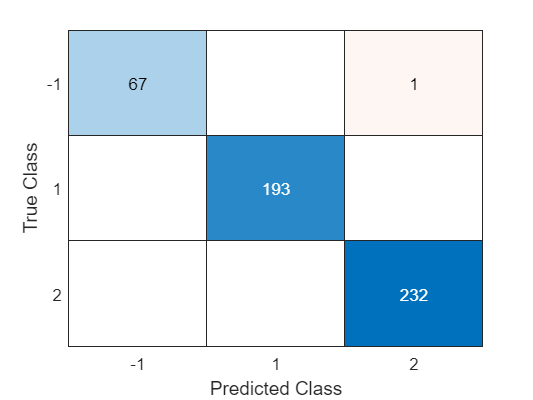

j = 2

j = 3

j = 4

j = 5

j = 6

j = 7

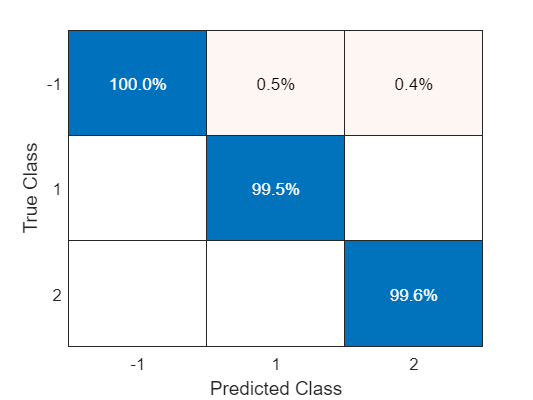

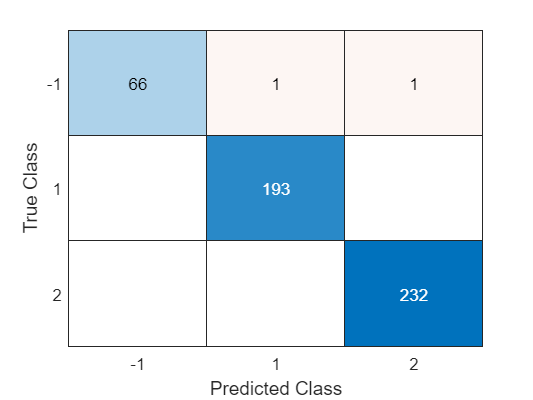

j = 8

j = 9

j = 10

for j=1:1:10
    j
    Mdl = fitcknn(Xtraindata,Ytraindata,'NumNeighbors',j,'Standardize',1);
    pre=predict(Mdl,Xtestdata);
    for i=1:1:length(Ytestdata)
        if isequal(Ytestdata(i,1),pre(i,1))
        hit=hit+1;
        end
    end
    %plot of confusion matrix and the accuracy 
    figure
    confusionchart(Ytestdata,pre,'Normalization','column-normalized')
    figure
    confusionchart(Ytestdata,pre)
    accuracy(j,1)=(hit/length(Ytestdata))*100;
    hit=0;
    
end

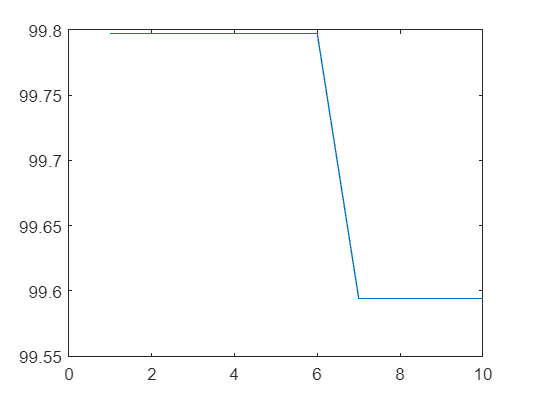

plot(accuracy)